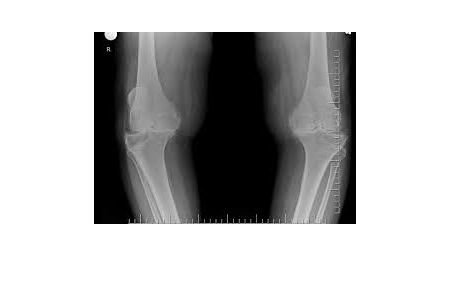

img =   Image with properties:

           CData: [192×262×3 uint8]
    CDataMapping: 'direct'

  Show all properties


% Read the X-ray image
xray_image = imread("C:\Users\88017\Downloads\orthoyes.jpg");
img=imshow(xray_image)

% Convert the X-ray image to grayscale if necessary
if size(xray_image, 3) == 3
    xray_image_gray = rgb2gray(xray_image);
else
    xray_image_gray = xray_image;
end

% Perform global thresholding
global_threshold = 0.5;
binary_global = imbinarize(xray_image_gray, global_threshold);

% Perform adaptive thresholding
binary_adaptive = imbinarize(xray_image_gray, 'adaptive');

% Perform multilevel segmentation
num_segments = 3;
threshold_values = multithresh(xray_image_gray, num_segments);
segmented_image = imquantize(xray_image_gray, threshold_values);

% Calculate the percentage of bone area relative to the total area of meat and bones
bone_area = sum(segmented_image(:) == 3); % Assuming bone region is labeled as 3
meat_area = sum(segmented_image(:) == 2); % Assuming meat region is labeled as 2
total_area = bone_area + meat_area;
bone_percentage = (bone_area / total_area) * 100

bone_percentage = 54.6153

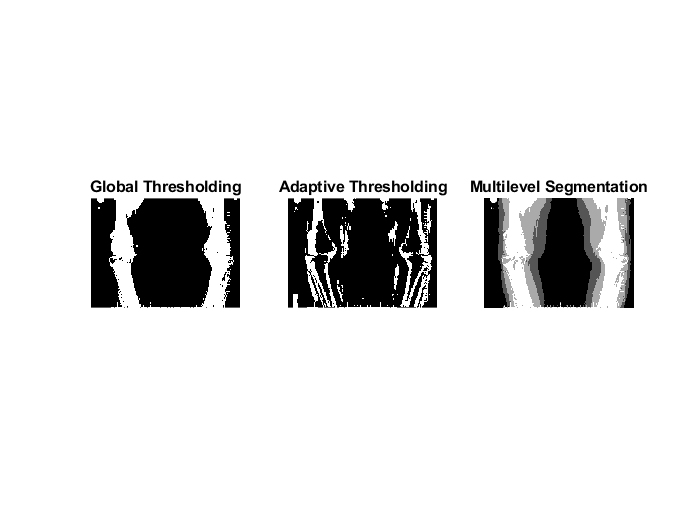


% Display the thresholded images
figure;
subplot(1, 3, 1), imshow(binary_global), title('Global Thresholding');
subplot(1, 3, 2), imshow(binary_adaptive), title('Adaptive Thresholding');
subplot(1, 3, 3), imshow(segmented_image, []), title('Multilevel Segmentation');


% Check if the thresholded value indicates osteoporosis
threshold_value_osteoporosis = 40; % Adjust as needed
if bone_percentage < threshold_value_osteoporosis
    disp('The patient has osteoporosis.');
else
    disp('The patient does not have osteoporosis.');
end

The patient does not have osteoporosis.



% Display the bone percentage
fprintf('Percentage of bone area to the total area of meat and bones: %.2f%%\n', bone_percentage);

Percentage of bone area to the total area of meat and bones: 54.62%


% Read the X-ray image
xray_image = imread("C:\Users\88017\Downloads\healthyh.jpg");

% Convert the X-ray image to grayscale if necessary
if size(xray_image, 3) == 3
    xray_image_gray = rgb2gray(xray_image);
else
    xray_image_gray = xray_image;
end







% Perform edge detection
edge_image = edge(xray_image_gray, 'Canny');

% Fill small gaps and holes in the edges
filled_edges = imfill(edge_image, 'holes');

% Perform morphological operations to enhance fractures
se = strel('line', 5, 90); % Adjust the line length and orientation as needed
morph_processed = imclose(filled_edges, se);

% Remove small isolated regions (noise) from the binary image
min_fracture_size = 10; % Adjust as needed
morph_processed_cleaned = bwareaopen(morph_processed, min_fracture_size);

% Calculate the percentage of bone area relative to the total area of the image
bone_area = sum(morph_processed_cleaned(:)); % Count pixels indicating fractures
total_area = numel(morph_processed_cleaned); % Total number of pixels
bone_percentage = (bone_area / total_area) * 100;

% Detect joint space narrowing (potential sign of osteoarthritis)
joint_space_narrowing_threshold =10 % Adjust as needed

joint_space_narrowing_threshold = 10

joint_space_narrowing = bone_percentage < joint_space_narrowing_threshold;

% Display the fracture detection result
if bone_percentage > 0 % If any fractures are detected
    disp('Fracture detected in the X-ray image.');
else
    disp('No fracture detected in the X-ray image.');
end

Fracture detected in the X-ray image.



% Display joint space narrowing detection result
if joint_space_narrowing
    disp('Potential joint space narrowing detected (possible osteoarthritis).');
else
    disp('No joint space narrowing detected.');
end

No joint space narrowing detected.


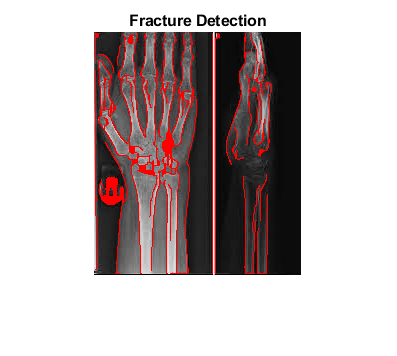


% Overlay detected fractures on the original X-ray image
overlay_image = imoverlay(xray_image_gray, morph_processed_cleaned, [1 0 0]); % Red overlay

% Display the overlay image
figure;
imshow(overlay_image);
title('Fracture Detection');